# Milling and Welding Todo

I have solved for you as an example the drilling task. Similar procedure ought to be done with welding task

See the video: [https://youtu.be/cVZWm9ORY30](https://youtu.be/cVZWm9ORY30)

As you can see in the video a Robot Arm perform three task. Only two tasks are shown: 

- Make a hole of 0.2 meter in a cylinder by drilling it. Observe that the tool mantain the same orientation during the drilling task.

- Insertion of a smaller cylinder not recorder here. 

- Welding the two cylinder. Observe that the tool always form a 45º among the two cylinder axis

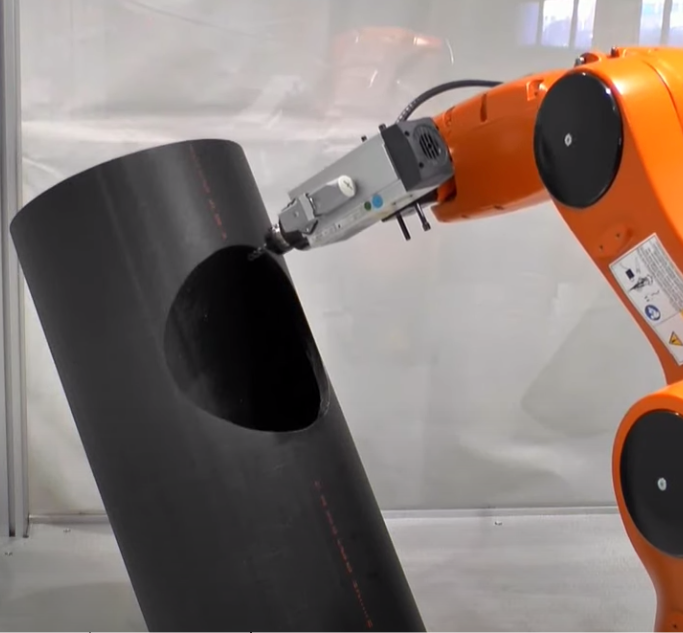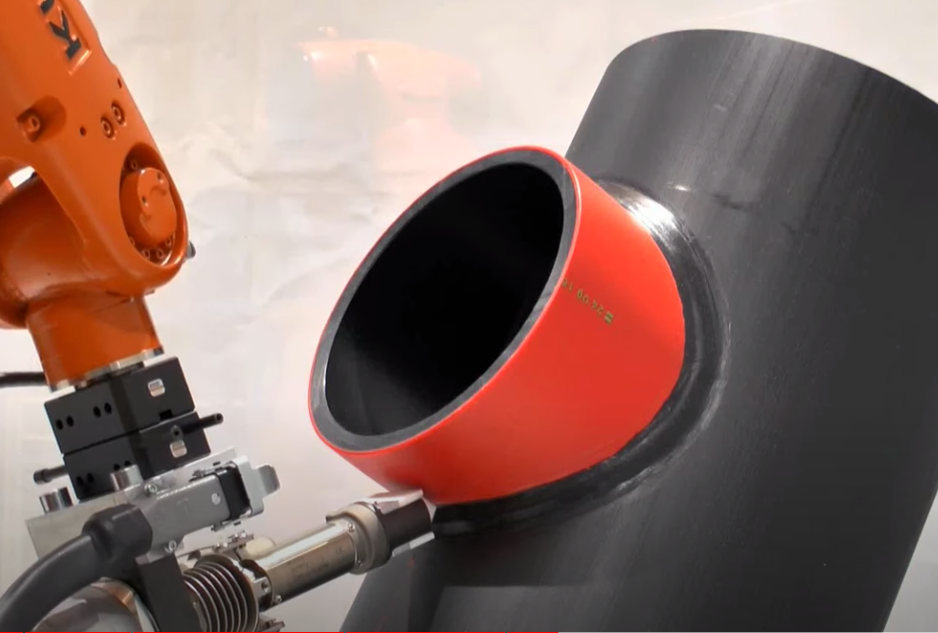

## Load the cylinder data

clear;
close all;
clf
load('F_V_cylinder.mat');

## **Plot the robot to initial position**

Pay attention how to move the robot base and add a tool

radius=0.20;
mdl_puma560
p560.base = transl(-0.1, 0, 0)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-0.1, 0, 0), RPY/xyz = (0, 0, 0) deg               
 


p560.tool=transl(0,0,0.15)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-0.1, 0, 0), RPY/xyz = (0, 0, 0) deg               
tool:    t = (0, 0, 0.15), RPY/xyz = (0, 0, 0) deg               
 


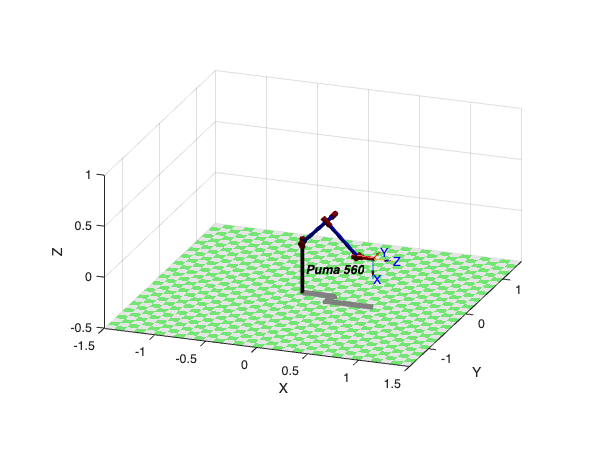

p560.plot(qn,'zoom',2.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],'view',[20 20] );
hold on

## Visualize the cylinder

Cy_scale=0.25

Cy_scale = 0.2500

CY_pose=transl([-0.3 0.3 -0.35])*troty(-pi/6) * trotx(-pi/6)

CY_pose =     0.8660    0.2500   -0.4330   -0.3000
         0    0.8660    0.5000    0.3000
    0.5000   -0.4330    0.7500   -0.3500
         0         0         0    1.0000


V_cy_drill = CY_pose*[Cy_scale.*V_cy'; ones(1,length(V_cy))] 

V_cy_drill =    -0.0835   -0.1063   -0.1291   -0.1519   -0.1747   -0.1974   -0.2202   -0.2430   -0.2658   -0.2886   -0.3114   -0.3342   -0.3570   -0.3798   -0.4026   -0.4253   -0.4481   -0.4709   -0.4937   -0.5165   -0.0755   -0.0983   -0.1210   -0.1438   -0.1666   -0.1894   -0.2122   -0.2350   -0.2578   -0.2806   -0.3034   -0.3262   -0.3489   -0.3717   -0.3945   -0.4173   -0.4401   -0.4629   -0.4857   -0.5085   -0.0761   -0.0988   -0.1216   -0.1444   -0.1672   -0.1900   -0.2128   -0.2356   -0.2584   -0.2812
    0.3000    0.3263    0.3526    0.3789    0.4053    0.4316    0.4579    0.4842    0.5105    0.5368    0.5632    0.5895    0.6158    0.6421    0.6684    0.6947    0.7211    0.7474    0.7737    0.8000    0.3422    0.3686    0.3949    0.4212    0.4475    0.4738    0.5001    0.5264    0.5528    0.5791    0.6054    0.6317    0.6580    0.6843    0.7107    0.7370    0.7633    0.7896    0.8159    0.8422    0.3829    0.4092    0.4355    0.4618    0.4881    0.5144    0.5407    0.5671    0.

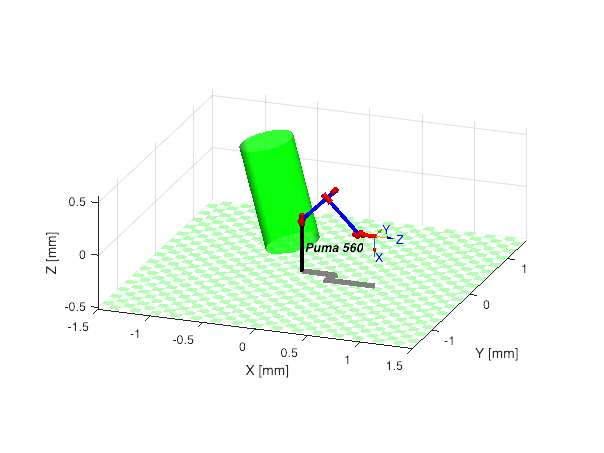

FVsPlot(F_cy,V_cy_drill(1:3,:)',[0 1 0])

## Draw drill task profile

Drill hole center 'D_h_c'

D_h_c=CY_pose*transl(0,0,0.6)*trotx(-pi/2)*troty(-pi/4)*transl(0,0,-0.25)

D_h_c =     0.7891    0.4330   -0.4356   -0.4509
    0.6124   -0.5000    0.6124    0.4469
    0.0474   -0.7500   -0.6597    0.2649
         0         0         0    1.0000


Drill poses

n=60

n = 60

for i=1:n
Drill_Pose(:,:,i)= D_h_c*trotz(2*pi*i/n)*transl(radius, 0,0);
end

Plotting Drill poses. Notice 'z' axis of the poses 

cir=transl(Drill_Pose)'

cir =    -0.2849   -0.2785   -0.2740   -0.2715   -0.2709   -0.2723   -0.2757   -0.2809   -0.2881   -0.2970   -0.3076   -0.3198   -0.3334   -0.3483   -0.3643   -0.3813   -0.3990   -0.4173   -0.4360   -0.4548   -0.4736   -0.4922   -0.5103   -0.5277   -0.5443   -0.5599   -0.5743   -0.5873   -0.5988   -0.6087   -0.6169   -0.6233   -0.6278   -0.6303   -0.6309   -0.6295   -0.6261   -0.6209   -0.6137   -0.6048   -0.5942   -0.5820   -0.5684   -0.5535   -0.5375   -0.5205   -0.5028   -0.4845   -0.4658   -0.4470
    0.5583    0.5459    0.5325    0.5181    0.5030    0.4872    0.4710    0.4545    0.4380    0.4215    0.4054    0.3896    0.3746    0.3603    0.3469    0.3347    0.3236    0.3140    0.3057    0.2991    0.2940    0.2906    0.2890    0.2890    0.2908    0.2943    0.2995    0.3063    0.3147    0.3244    0.3356    0.3479    0.3613    0.3757    0.3908    0.4066    0.4228    0.4393    0.4558    0.4723    0.4884    0.5042    0.5193    0.5336    0.5469    0.5592    0.5702    0.5799    0.5881   

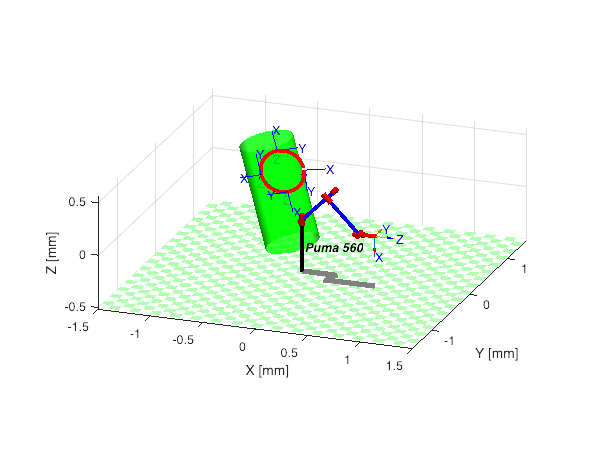

hold on
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);
%axis([-1.5 1.5 -1.5 1.5 -0.5 1])
axis equal
trplot(Drill_Pose(:,:,1), 'length',0.2)
trplot(Drill_Pose(:,:,15), 'length',0.2)
trplot(Drill_Pose(:,:,30), 'length',0.2)
trplot(Drill_Pose(:,:,45), 'length',0.2)

## Executing the drilling task

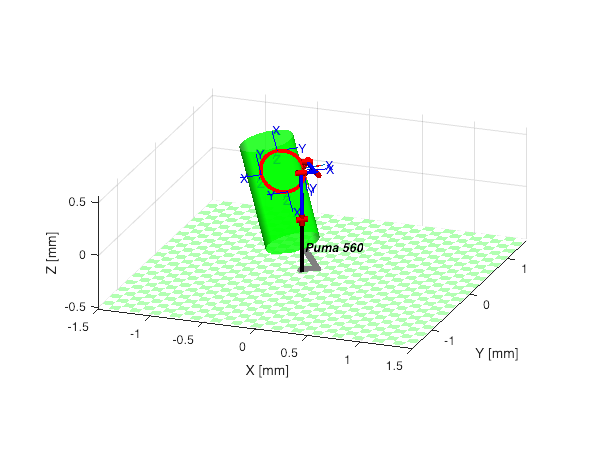

Q= p560.ikine6s(Drill_Pose, 'run');
p560.plot(Q,'view',[20 20], 'zoom',1.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],...
    'trail','-','jaxes','zoom',2)

## Functions

function T_b_a=FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
axis equal
end